%国家类型判别的BP网络（原始数据）
clear                                       %清理内存
P=[79.1	76.8 80.0 78.7 73.1 75.0 75.8 66.7 71.3	70.7 72.9 69.8 69.4 66.7
99.0 99.0 99.0 99.0 96.7 74.6 96.4 99.5	98.2 91.2 99.0 92.8 77.8 53.7
23582 29605 23257 25512	12013 17719	3967 6460 4809 6006 3353 4288 4036 3041];
                                            %输入变量
T=[1 1 1 1 1 1 0 0 0 0 0 0 0 0];            %目标输出
net=newff(minmax(P),[1,1],{'logsig','purelin'},'trainlm');

          See help for NEWFF to update calls to the new argument list.
 


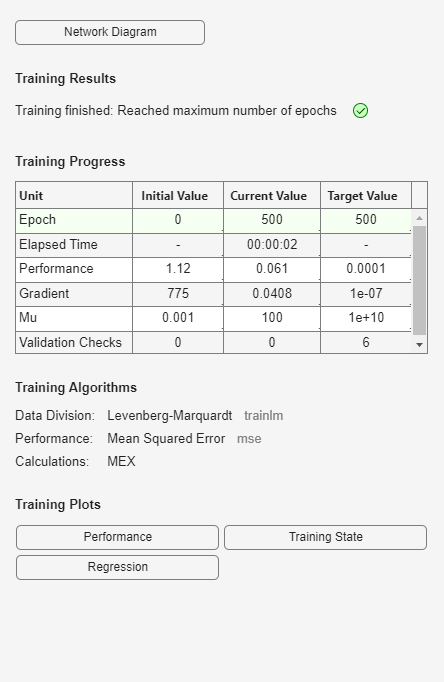

                                            %创建一个隐含层包括4个神经元的BP网络
net.trainParam.epochs=500;                  %最大学习次数
net.trainParam.goal=0.0001;                 %训练误差0.0001，小于次数可以终止学习
net=train(net,P,T);                         %训练网络

Y=sim(net,P);                               %训练样本的仿真结果
P_test=[78.7 78.2 70.2 68.0
99.0 96.9 97.9 82.8
20659 13943	5648 3105];                     %待判样品测试
Yt=sim(net,P_test);                         %待判样品的仿真结果

%进一步的运算
for i=1:length(Y)                           %将训练样本仿真结果转换为0-1表示
    if Y(i)>=0.5
        y(i)=1;
    else
        y(i)=0;
    end
end
y                                           %输出训练样本的分类

y =      1     1     1     1     1     1     0     0     0     0     0     0     0     1


r=1-sum(abs(y-T))/length(Y)                 %计算分类正确率

r = 0.9286

for i=1:length(Yt)                          %将待判样品的仿真结果转换为0-1表示
    if Yt(i)>=0.5
        yt(i)=1;
    else
        yt(i)=0;
    end
end
yt                                          %输出待判样品分类

yt =      1     1     0     0
